# One sample analyses

**Author:** Scott Campit

## Summary

This script analyzes single cell line datasets and plots the relationship between fluxes and histone levels

## Load datasets

### Khao et al., 2020

#### Load metabolic flux data

load ~/Data/CBM/eGEM/_Fluxes/Khao_no_gamma.mat

#### Load proteomics data

filepaths = '~/Data/Proteomics/Dou/Khoa et al 2020 Histone PTMs.xlsx';
sheet = 'Single modifications';
khao_proteomics = readcell(filepaths, 'Sheet', sheet);

Extract information

marker_labels = string(khao_proteomics(2:end, 1));
log2fc = str2double(string(khao_proteomics(2:end, 14)));
log2fc(isnan(log2fc)) = 0;
pvalues = str2double(string(khao_proteomics(2:end, 15))); 
pvalues(isnan(pvalues)) = 0;

Sort the data

[~, idx] = sort(marker_labels);
marker_labels = marker_labels(idx);
log2fc = log2fc(idx);

Reorganize the data

marker_pos = [15, 16, 17, 14, ... % H3K4  me1, me2, me3, ac
              27, 28, 29, 26, ... % H3K9  me1, me2, me3, ac
              8, 9, 10, 7, ...    % H3K27 me1, me2, me3, ac
              11, 12, 13, ...     % H3K36 me1, me2, me3
              23, 24, 25, 22];    % H3K79 me1, me2, me3, ac
          
marker_labels = marker_labels(marker_pos);
log2fc = log2fc(marker_pos);
pvalues = pvalues(marker_pos);

#### Plot the metabolic flux versus the relative proteomics levels

flux_pos = [6, 7, 8, 9, ...
            10, 11, 12, 13, ...
            14, 15, 16, 17, ...
            18, 19, 20, ...
            22, 23, 24, 25];
        
for i = 1:length(flux_pos)
    flux_data{i} = flux{flux_pos(i)};
end

rxn_pos = [3780, 3781, 3782, 3783, ... % H3K4  me1, me2, me3, ac
           3784, 3785, 3786, 3787, ... % H3K9  me1, me2, me3, ac
           3788, 3789, 3790, 3791, ... % H3K27 me1, me2, me3, ac
           3792, 3793, 3794, ...       % H3K36 me1, me2, me3
           3796, 3797, 3798, 3799];    % H3K79 me1, me2, me3, ac
for i = 1:length(rxn_pos)
    rxn_flux(i, 1) = flux_data{i}(rxn_pos(i));
end

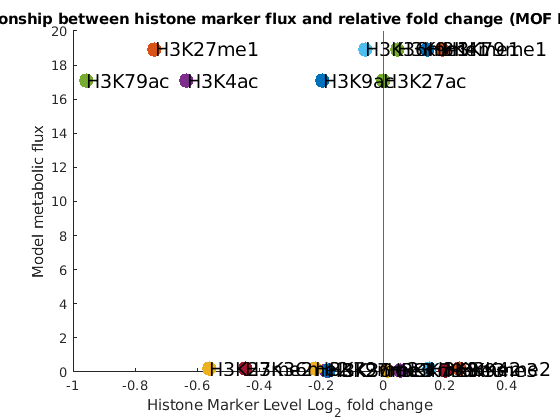

figure;
% Note that all markers were not differentially expressed
%for i = 1:length(rxn_flux)
%    if pvalues(i) > 0.05
%        colors(i) = 'k';
%   else
%        colors(i) = 'r';
%    end
%end
for i = 1:length(rxn_flux)
    hold on;
    scatter(log2fc(i), rxn_flux(i), 120, 'filled');
    hold off;
end
xlabel("Histone Marker Level Log_{2} fold change");
ylabel("Model metabolic flux");
title("Relationship between histone marker flux and relative fold change (MOF KO / WT)");
text(log2fc, rxn_flux, marker_labels, 'FontSize', 14)
xline(0)

### Lu et al., 2020

#### Load metabolic flux data

load ~/Data/CBM/eGEM/_Fluxes/lu_no_gamma.mat

#### Load proteomics data

filepaths = '~/Data/Proteomics/Dou/Khoa et al 2020 Histone PTMs.xlsx';
sheet = 'Single modifications';
khao_proteomics = readcell(filepaths, 'Sheet', sheet);

Extract information

marker_labels = string(khao_proteomics(2:end, 1));
log2fc = str2double(string(khao_proteomics(2:end, 14)));
log2fc(isnan(log2fc)) = 0;
pvalues = str2double(string(khao_proteomics(2:end, 15))); 
pvalues(isnan(pvalues)) = 0;

Sort the data

[~, idx] = sort(marker_labels);
marker_labels = marker_labels(idx);
log2fc = log2fc(idx);

Reorganize the data

marker_pos = [15, 16, 17, 14, ... % H3K4  me1, me2, me3, ac
              27, 28, 29, 26, ... % H3K9  me1, me2, me3, ac
              8, 9, 10, 7, ...    % H3K27 me1, me2, me3, ac
              11, 12, 13, ...     % H3K36 me1, me2, me3
              23, 24, 25, 22];    % H3K79 me1, me2, me3, ac
          
marker_labels = marker_labels(marker_pos);
log2fc = log2fc(marker_pos);
pvalues = pvalues(marker_pos);

#### Plot the metabolic flux versus the relative proteomics levels

flux_pos = [6, 7, 8, 9, ...
            10, 11, 12, 13, ...
            14, 15, 16, 17, ...
            18, 19, 20, ...
            22, 23, 24, 25];
        
for i = 1:length(flux_pos)
    flux_data{i} = flux{flux_pos(i)};
end

rxn_pos = [3780, 3781, 3782, 3783, ... % H3K4  me1, me2, me3, ac
           3784, 3785, 3786, 3787, ... % H3K9  me1, me2, me3, ac
           3788, 3789, 3790, 3791, ... % H3K27 me1, me2, me3, ac
           3792, 3793, 3794, ...       % H3K36 me1, me2, me3
           3796, 3797, 3798, 3799];    % H3K79 me1, me2, me3, ac
for i = 1:length(rxn_pos)
    rxn_flux(i, 1) = flux_data{i}(rxn_pos(i));
end

figure;
% Note that all markers were not differentially expressed
%for i = 1:length(rxn_flux)
%    if pvalues(i) > 0.05
%        colors(i) = 'k';
%   else
%        colors(i) = 'r';
%    end
%end
for i = 1:length(rxn_flux)
    hold on;
    scatter(log2fc(i), rxn_flux(i), 120, 'filled');
    hold off;
end
xlabel("Histone Marker Level Log_{2} fold change");
ylabel("Model metabolic flux");
title("Relationship between histone marker flux and relative fold change (MOF KO / WT)");
text(log2fc, rxn_flux, marker_labels, 'FontSize', 14)
xline(0)

### Yadav et al

#### Load metabolic flux data

load ~/Data/CBM/eGEM/_Fluxes/yadav_no_gamma.mat

#### Load proteomics data

filepaths = '~/Data/Proteomics/Dou/Khoa et al 2020 Histone PTMs.xlsx';
sheet = 'Single modifications';
khao_proteomics = readcell(filepaths, 'Sheet', sheet);

Extract information

marker_labels = string(khao_proteomics(2:end, 1));
log2fc = str2double(string(khao_proteomics(2:end, 14)));
log2fc(isnan(log2fc)) = 0;
pvalues = str2double(string(khao_proteomics(2:end, 15))); 
pvalues(isnan(pvalues)) = 0;

Sort the data

[~, idx] = sort(marker_labels);
marker_labels = marker_labels(idx);
log2fc = log2fc(idx);

Reorganize the data

marker_pos = [15, 16, 17, 14, ... % H3K4  me1, me2, me3, ac
              27, 28, 29, 26, ... % H3K9  me1, me2, me3, ac
              8, 9, 10, 7, ...    % H3K27 me1, me2, me3, ac
              11, 12, 13, ...     % H3K36 me1, me2, me3
              23, 24, 25, 22];    % H3K79 me1, me2, me3, ac
          
marker_labels = marker_labels(marker_pos);
log2fc = log2fc(marker_pos);
pvalues = pvalues(marker_pos);

#### Plot the metabolic flux versus the relative proteomics levels

flux_pos = [6, 7, 8, 9, ...
            10, 11, 12, 13, ...
            14, 15, 16, 17, ...
            18, 19, 20, ...
            22, 23, 24, 25];
        
for i = 1:length(flux_pos)
    flux_data{i} = flux{flux_pos(i)};
end

rxn_pos = [3780, 3781, 3782, 3783, ... % H3K4  me1, me2, me3, ac
           3784, 3785, 3786, 3787, ... % H3K9  me1, me2, me3, ac
           3788, 3789, 3790, 3791, ... % H3K27 me1, me2, me3, ac
           3792, 3793, 3794, ...       % H3K36 me1, me2, me3
           3796, 3797, 3798, 3799];    % H3K79 me1, me2, me3, ac
for i = 1:length(rxn_pos)
    rxn_flux(i, 1) = flux_data{i}(rxn_pos(i));
end

figure;
% Note that all markers were not differentially expressed
%for i = 1:length(rxn_flux)
%    if pvalues(i) > 0.05
%        colors(i) = 'k';
%   else
%        colors(i) = 'r';
%    end
%end
for i = 1:length(rxn_flux)
    hold on;
    scatter(log2fc(i), rxn_flux(i), 120, 'filled');
    hold off;
end
xlabel("Histone Marker Level Log_{2} fold change");
ylabel("Model metabolic flux");
title("Relationship between histone marker flux and relative fold change (MOF KO / WT)");
text(log2fc, rxn_flux, marker_labels, 'FontSize', 14)
xline(0)